% close all
% clear all
% clc

## Quick data exploration

We start looking at univariate distributions. For example, we check for imbalanced classes

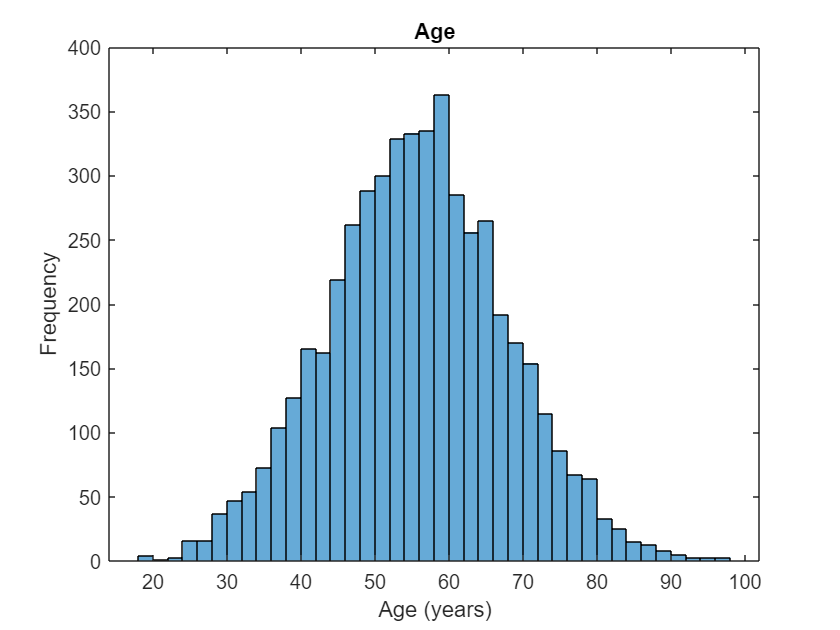

Data = Needs; % renaming

%age
figure
histogram(Data.Age)
title('Age')
xlabel('Age (years)')
ylabel('Frequency')

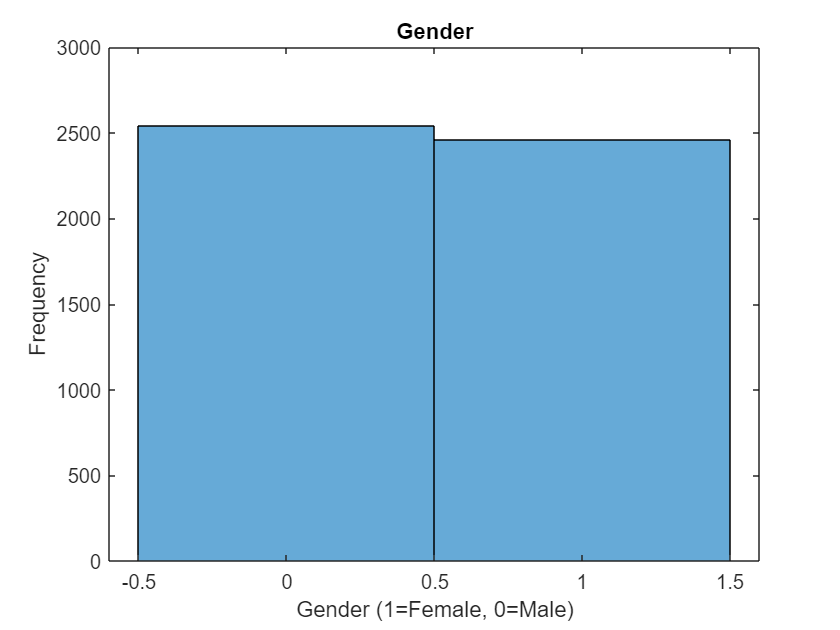

%Gender
figure
histogram(Data.Gender)
title('Gender')
xlabel('Gender (1=Female, 0=Male)')
ylabel('Frequency')

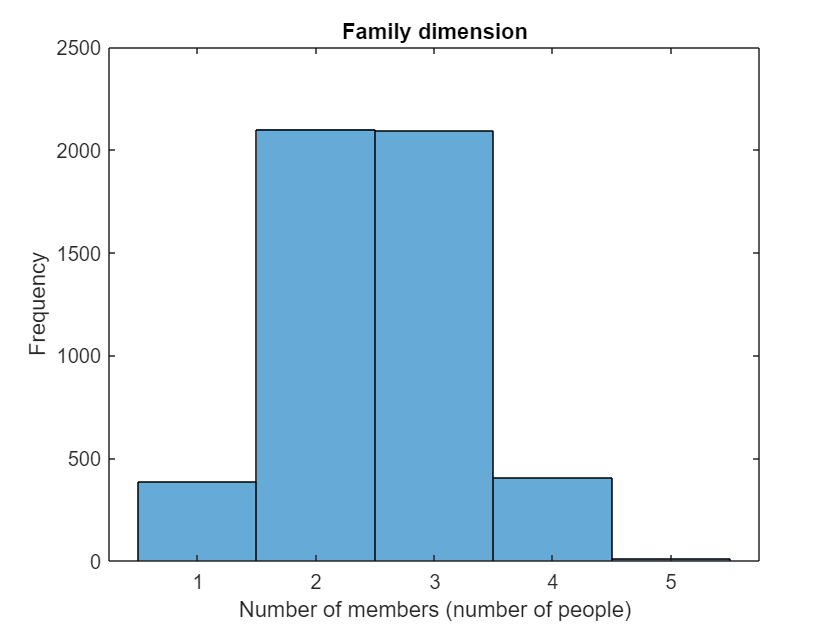

%Family dimension
figure
histogram(Data.FamilyMembers)
title('Family dimension')
xlabel('Number of members (number of people)')
ylabel('Frequency')

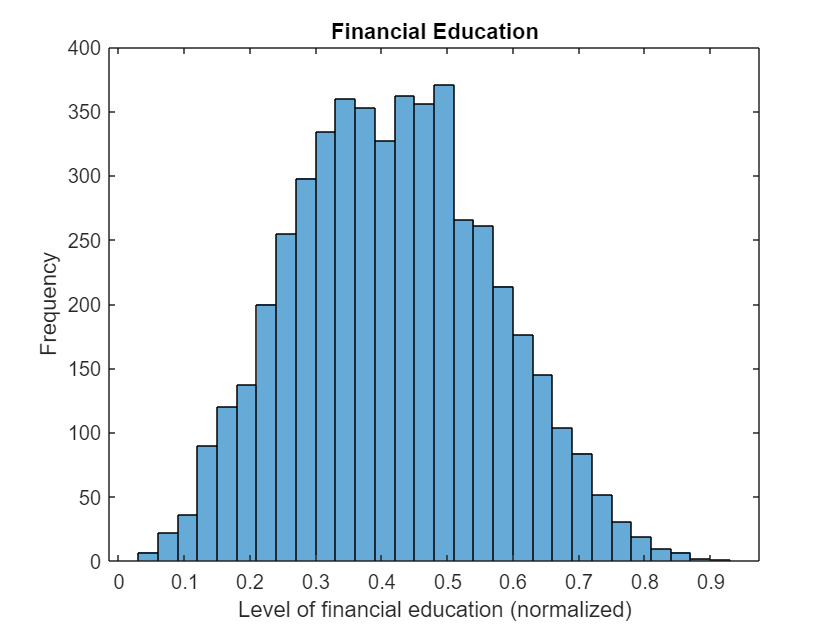

%Financial education
figure
histogram(Data.FinancialEducation)
title('Financial Education')
xlabel('Level of financial education (normalized)')
ylabel('Frequency')

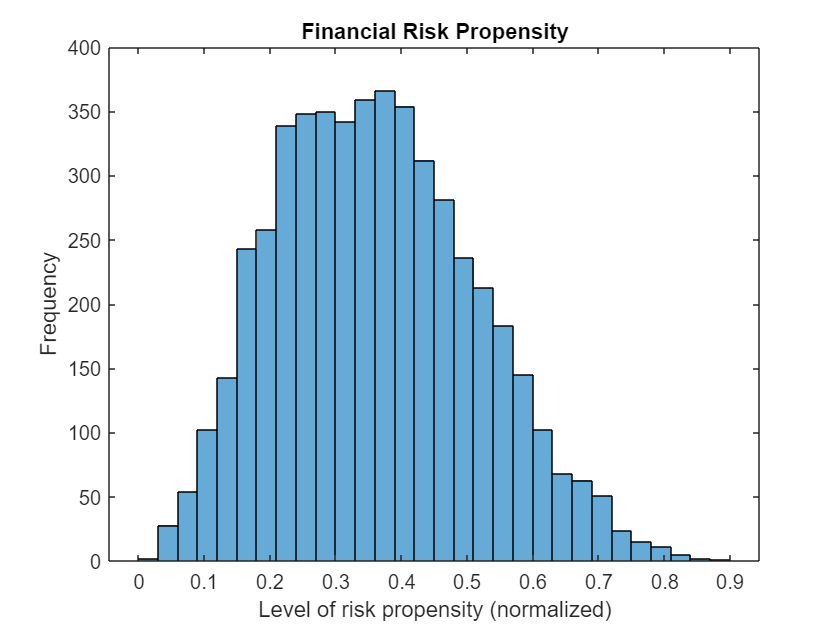

%Financial risk propensity
figure
histogram(Data.RiskPropensity)
title('Financial Risk Propensity')
xlabel('Level of risk propensity (normalized)')
ylabel('Frequency')

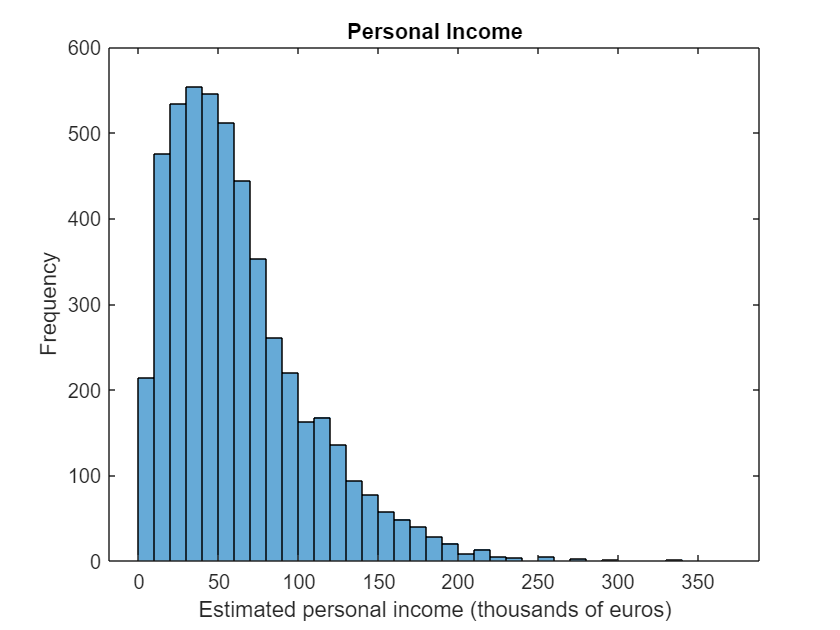

%income
figure
histogram(Data.Income)
title('Personal Income')
xlabel('Estimated personal income (thousands of euros)')
ylabel('Frequency')

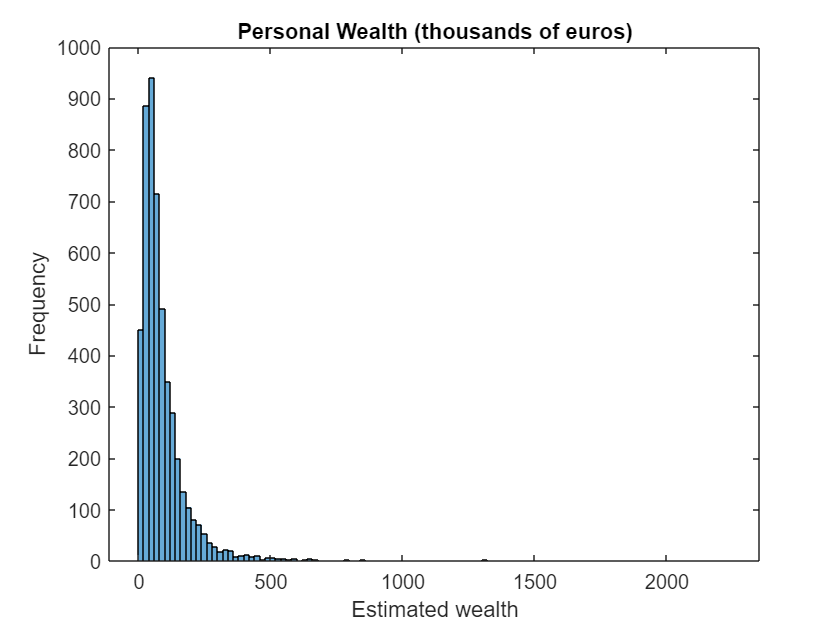

%wealth
figure
histogram(Data.Wealth)
title('Personal Wealth (thousands of euros)')
xlabel('Estimated wealth')
ylabel('Frequency')

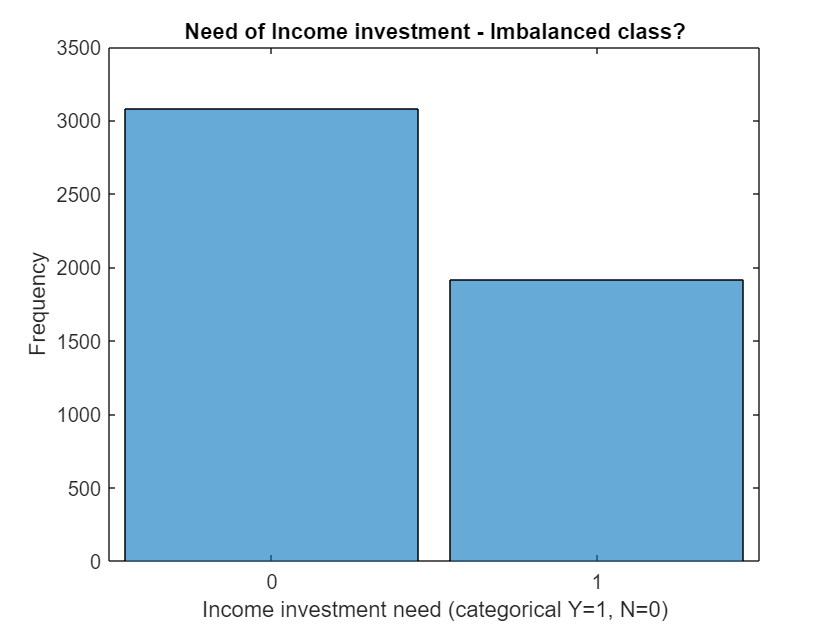

%Income investment
figure
histogram(Data.IncomeInvestment)
title('Need of Income investment - Imbalanced class?')
xlabel('Income investment need (categorical Y=1, N=0)')
ylabel('Frequency')

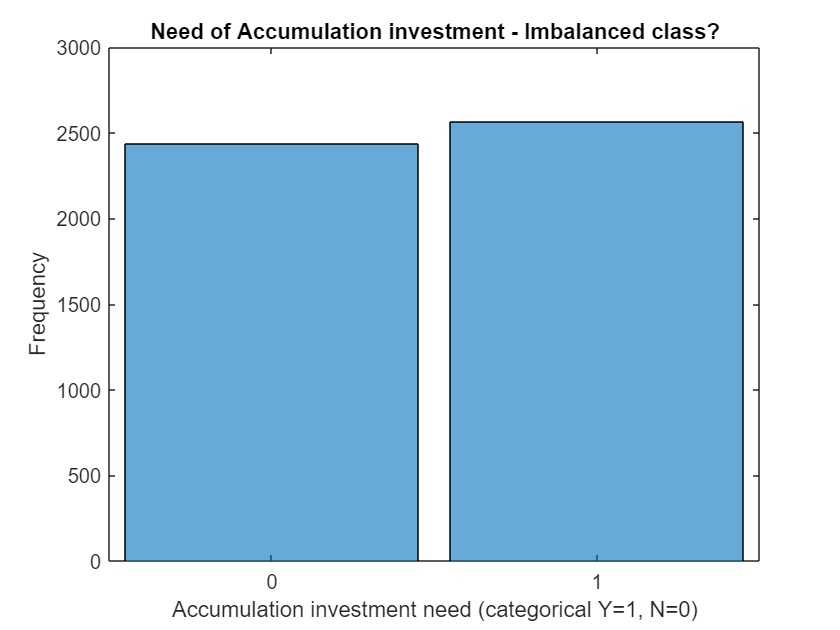

%Accumulation investment
figure
histogram(Data.AccumulationInvestment)
title('Need of Accumulation investment - Imbalanced class?')
xlabel('Accumulation investment need (categorical Y=1, N=0)')
ylabel('Frequency')

### Data transformation

Wealth and Income follow a power law, so we thought it better to use a log transformation and a boxcox transformation to make just a little bit extra nice.

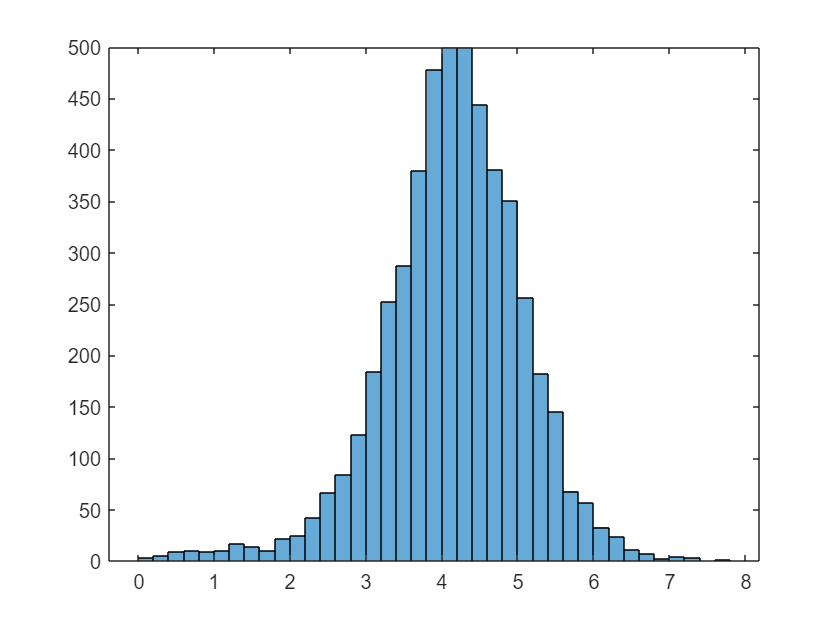

%wealth analysis
histogram(log(Data.Wealth)) % log transformation

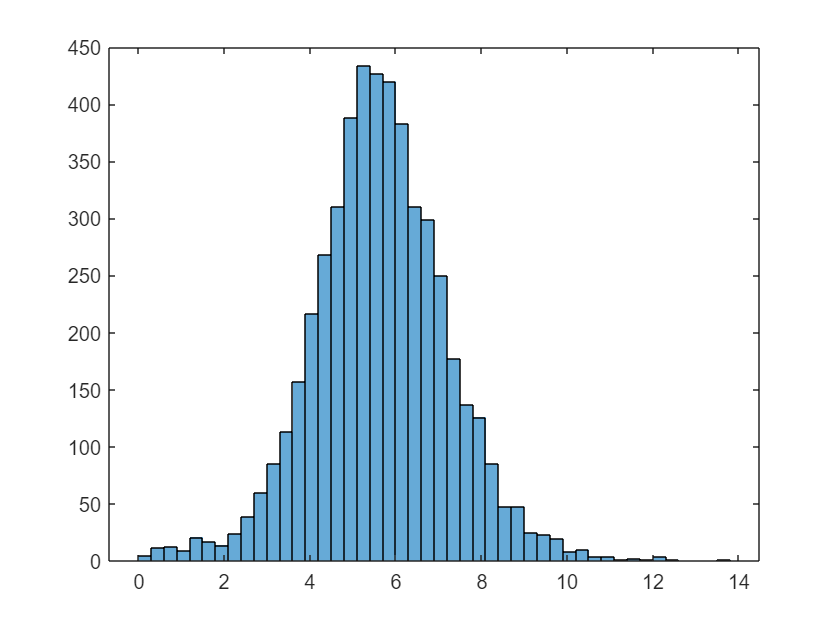

logWealth = log(Data.Wealth); % we'll go for the log-transformation
BoxWealth = boxcox(Data.Wealth);
histogram(BoxWealth); % Boxcox transformation

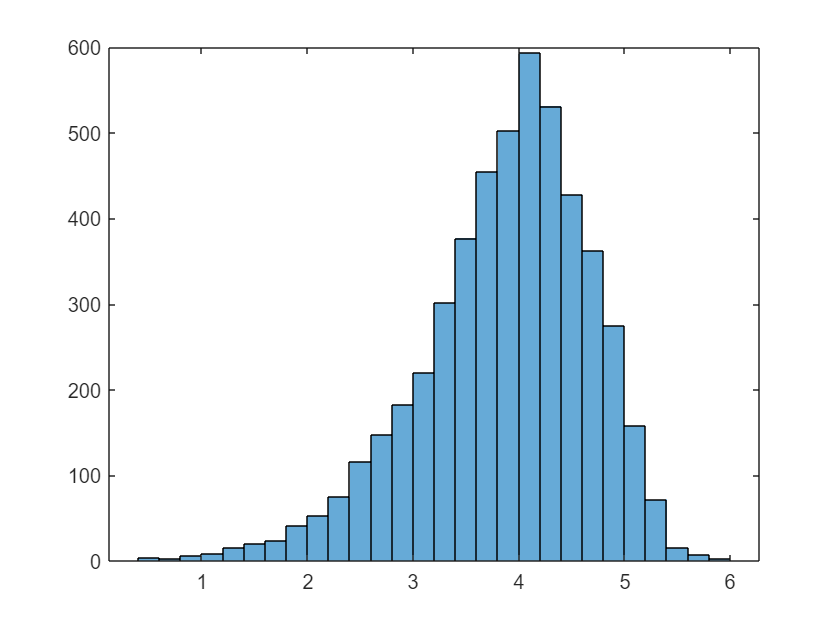

%income analysis
histogram(log(Data.Income)) % log transformation

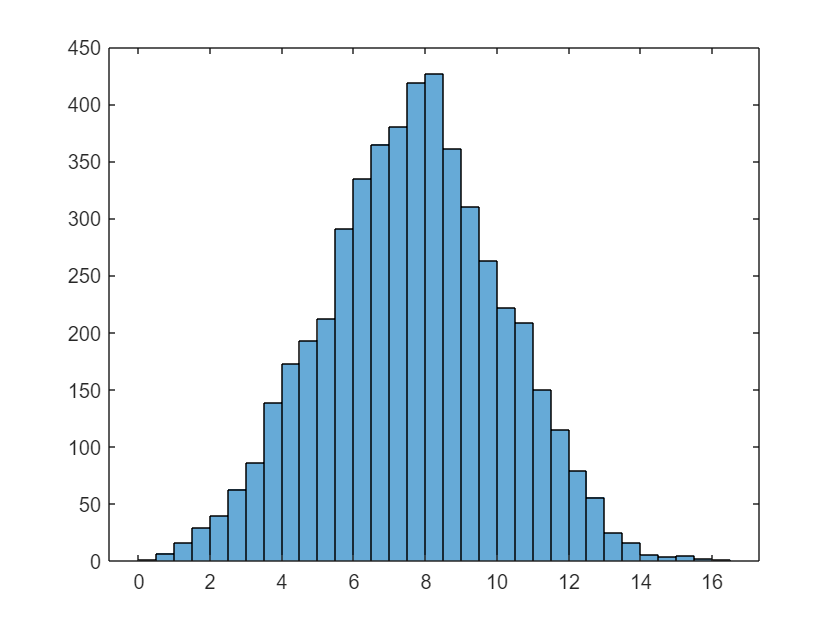

logIncome = log(Data.Income); % we'll go for the log transformation
BoxIncome = boxcox(Data.Income);
histogram(BoxIncome); % boxcox transformation

X =[zscore(Data.Age) Data.Gender zscore(Data.FamilyMembers) zscore(Data.FinancialEducation)...
    zscore(Data.RiskPropensity) zscore(BoxIncome) zscore(BoxWealth)];
Inc = [Data.IncomeInvestment];
Accum = [Data.AccumulationInvestment];
n = size(X,1);

## Dividing data

rng('default') % For reproducibility
hpartition = cvpartition(n,'Holdout',0.2); %splitting 80% training/validation and 20% testing
idxTrain = training(hpartition);
idxTest = test(hpartition);
nObs = size(Data, 1);
nObsTrain = round(0.8*nObs);

% we are now building response variables vectors (both for income and acc.
% classification) into training and testing
yInvIncTrain = Data.IncomeInvestment(idxTrain,:);
yInvAccTrain = Data.AccumulationInvestment(idxTrain,:);
yInvIncTest = Data.IncomeInvestment(idxTest,:);
yInvAccTest = Data.AccumulationInvestment(idxTest,:);

% training/testing matrices
XTrain = X(idxTrain,:);
XTest = X(idxTest,:);

% training/testing tables: defining variables names first
varNames    = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth'};
XTrainTable = table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7), 'VariableNames',varNames);
XTestTable = table(XTest(:,1), XTest(:,2), XTest(:,3), XTest(:,4), XTest(:,5), XTest(:,6), XTest(:,7), 'VariableNames',varNames);

Opening classification learner app...

wealthy = Data.Wealth>10;
SmallData = Data(wealthy,:);

Error using  () 
Subscripting into a table using one subscript (as in t(i)) is not supported. Specify a row subscript and a variable subscript, as in t(rows,vars). To select variables, use t(:,i) or for one variable t.(i). To select rows, use t(i,:).

Risktolerance = ( 0.6*zscore(SmallData.Age) + 0.3*zscore(SmallData.FinancialEducation) + 0.1*zscore(SmallData.RiskPropensity) ) ./ (logWealth(wealthy));
Xsmall = [zscore(Risktolerance) zscore(SmallData.Age) zscore(SmallData.FinancialEducation) BoxIncome(wealthy) BoxWealth(wealthy)];
YsmallAcc = SmallData.AccumulationInvestment;
YsmallInc = SmallData.IncomeInvestment;

figure
xnames = {'Risktolerance','Age', 'Financial Education', 'Income', 'Wealth'};
gplotmatrix(Xsmall,[],Data.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')
figure
xnames = {'Risktolerance','Age', 'Financial Education', 'Income', 'Wealth'};
gplotmatrix(Xsmall,[],Data.AccumulationInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

We create a smaller data table

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), 'VariableNames',xnames);
XsmallTestTable=table(XsmallTest(:,1), XsmallTest(:,2), XsmallTest(:,3), XsmallTest(:,4), XsmallTest(:,5), 'VariableNames', xnames);

For Accumulation:

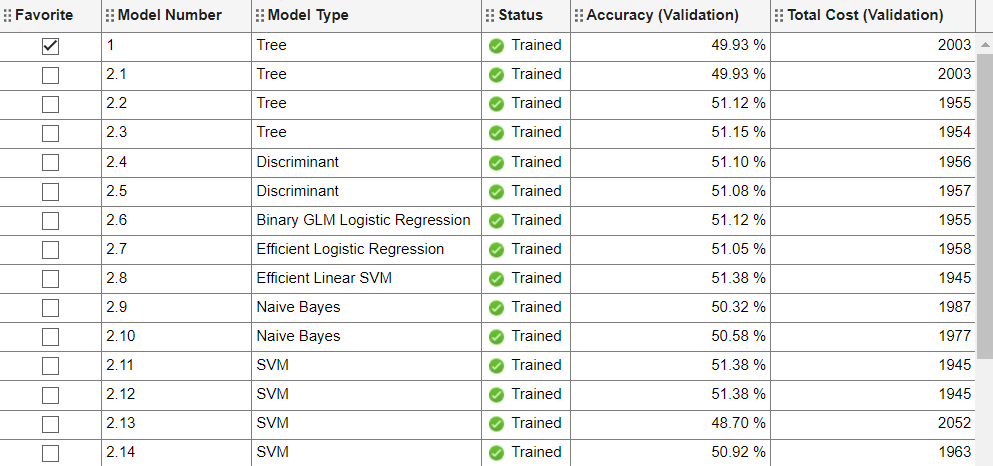

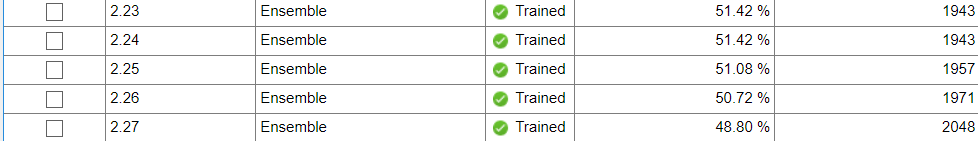

**Directly training and testing ensemble model **

response = yInvAccTrain;
rng('default')
template = templateTree('MaxNumSplits', 3999);
classificationEnsemble = fitcensemble(...
    XsmallTrainTable, ...
    response, ...
    'Method', 'Bag', ...                      bagged tree
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),... 
    'Cost', [0 1; 3 0],...                    misclassification costs
    'KFold', 10,...                           10-fold validation
    'CrossVal','on')

classificationEnsemble =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Bag'
         PredictorNames: {'Risktolerance'  'Age'  'Financial Education'  'Income'  'Wealth'}
           ResponseName: 'Y'
        NumObservations: 4000
                  KFold: 10
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [100 100 100 100 100 100 100 100 100 100]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods


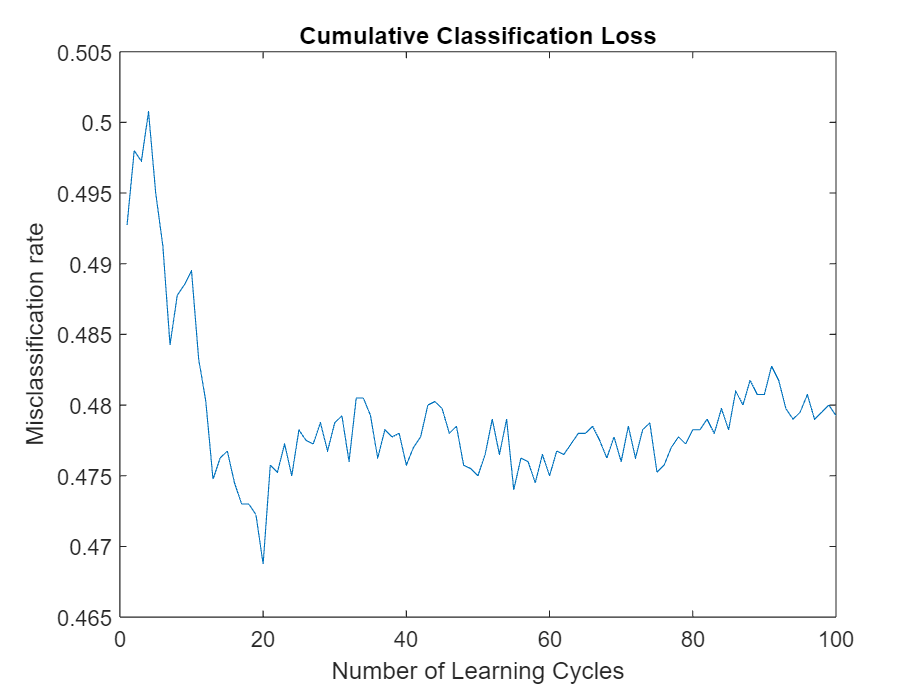

CVLoss = kfoldLoss(classificationEnsemble,'Mode','Cumulative');
figure;
plot(CVLoss);
xlabel('Number of Learning Cycles');
ylabel('Misclassification rate');
title('Cumulative Classification Loss')

estGenError = CVLoss(end)

estGenError = 0.4793

[labels, scores, cost] = kfoldPredict(classificationEnsemble);
tp = sum((labels == '1') & (response =='1'));
fp = sum((labels == '1') & (response =='0'));
fn = sum((labels == '0') & (response =='1'));
prec = tp / (tp + fp)

prec = 0.5193

rec = tp / (tp + fn)

rec = 0.9041

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.6597

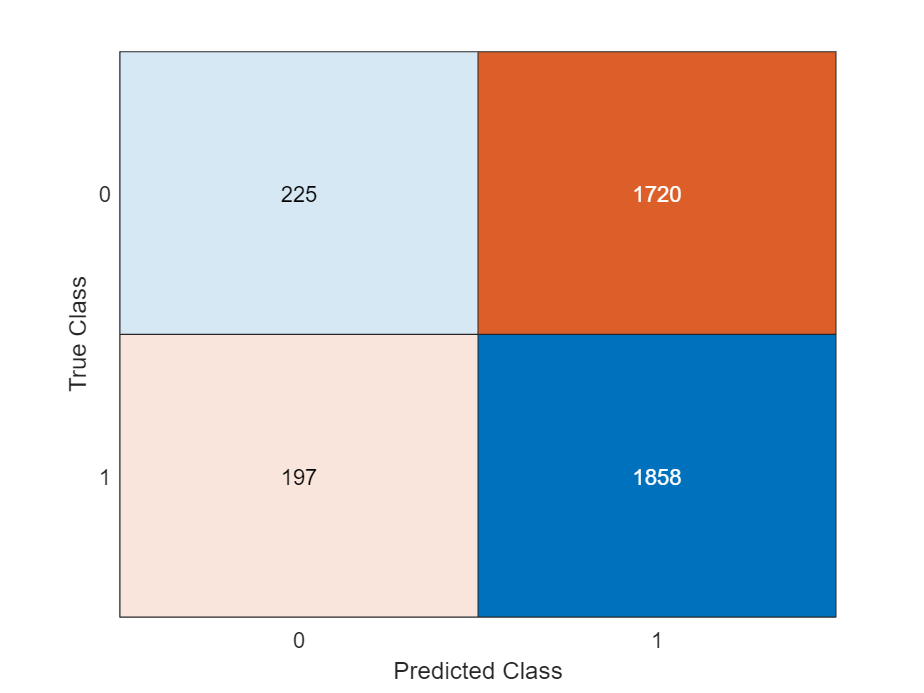

confusionchart(response, labels)

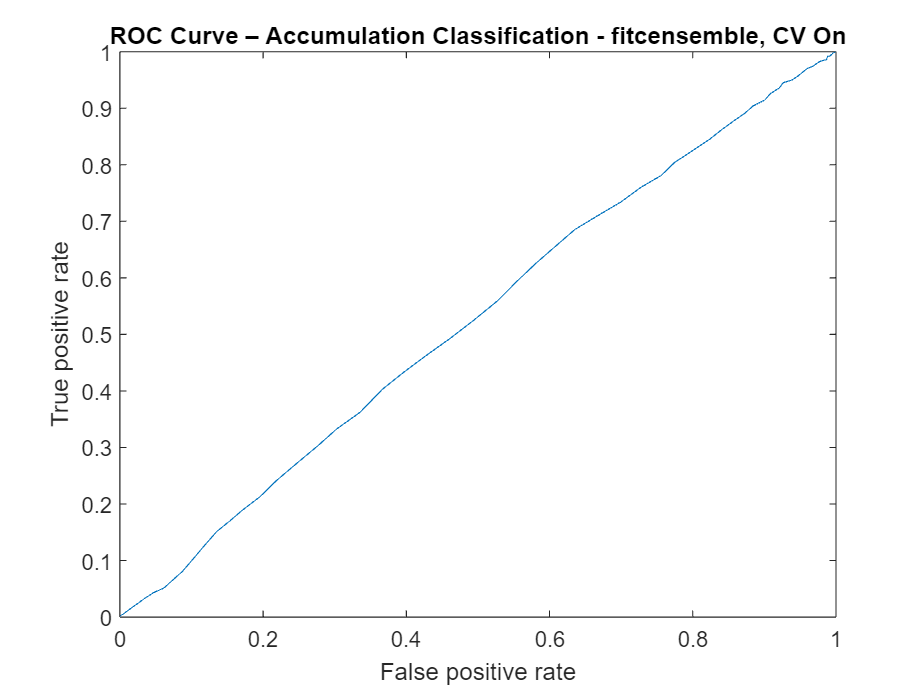

[X,Y,~,AUC] = perfcurve(response,scores(:,2),1);
figure
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve – Accumulation Classification - fitcensemble, CV On')

AUC

AUC = 0.5243

classificationEnsemble = fitcensemble(...
    XsmallTrainTable, ...
    response, ...
    'Method', 'Bag', ...
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),...
    'Cost', [0 1; 3 0],...
    'CrossVal','off')

classificationEnsemble =   ClassificationBaggedEnsemble
           PredictorNames: {'Risktolerance'  'Age'  'Financial Education'  'Income'  'Wealth'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 4000
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
                FResample: 1
                  Replace: 1
         UseObsForLearner: [4000×100 logical]


  Properties, Methods


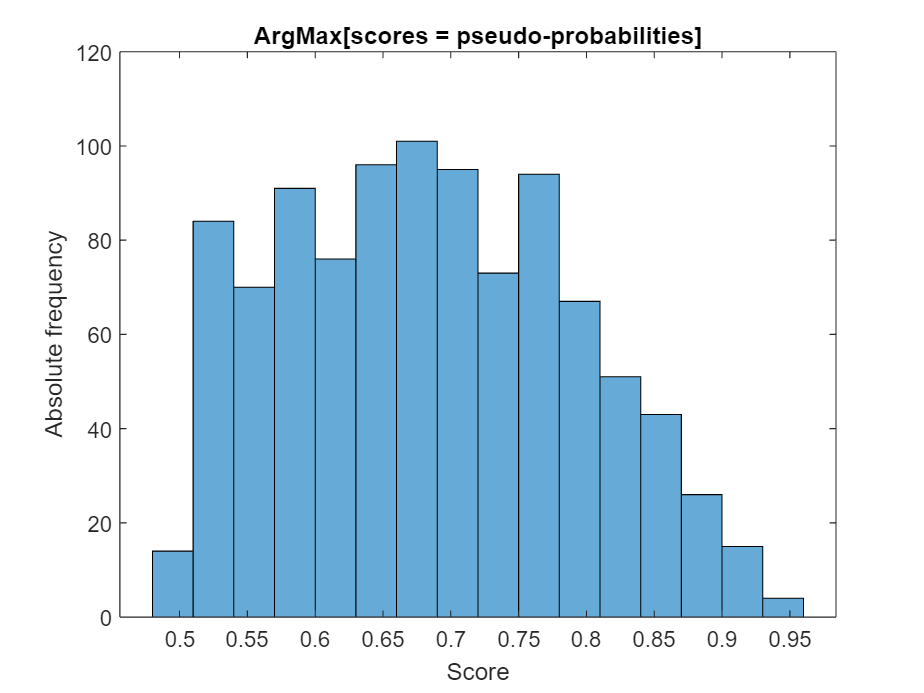

[labels,scores] = predict(classificationEnsemble,XsmallTestTable);
figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

tp = sum((labels == '1') & (yInvAccTest=='1'));
fp = sum((labels == '1') & (yInvAccTest=='0'));
fn = sum((labels == '0') & (yInvAccTest=='1'));
prec = tp / (tp + fp)

prec = 0.5103

rec = tp / (tp + fn)

rec = 0.8767

F1 = 2 * prec * rec / (prec + rec) 

F1 = 0.6451

rec = tp / (tp + fn)

rec = 0.8767

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.6451

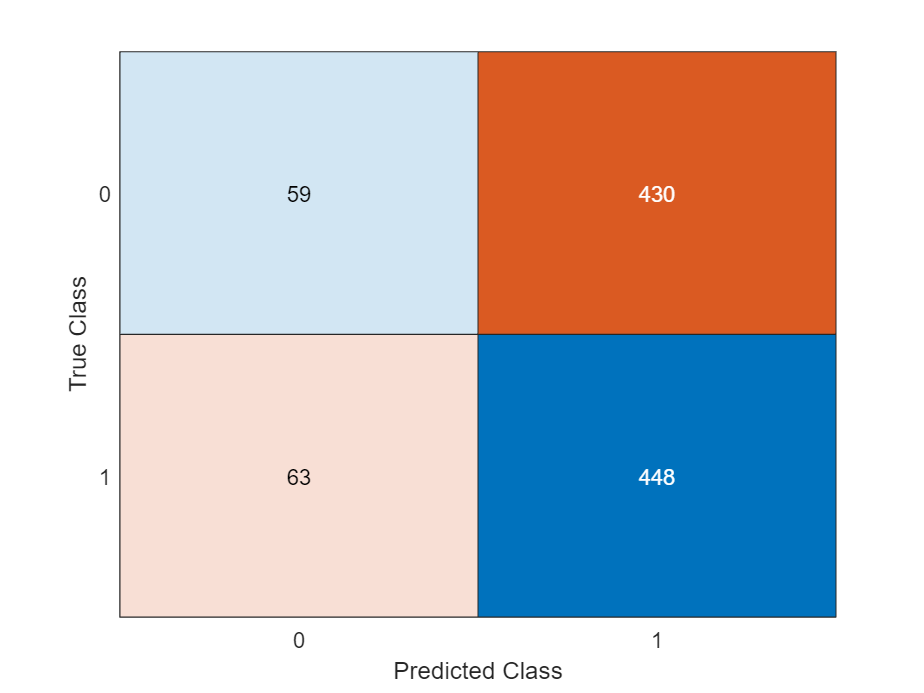

confusionchart(yInvAccTest, labels)

For income:

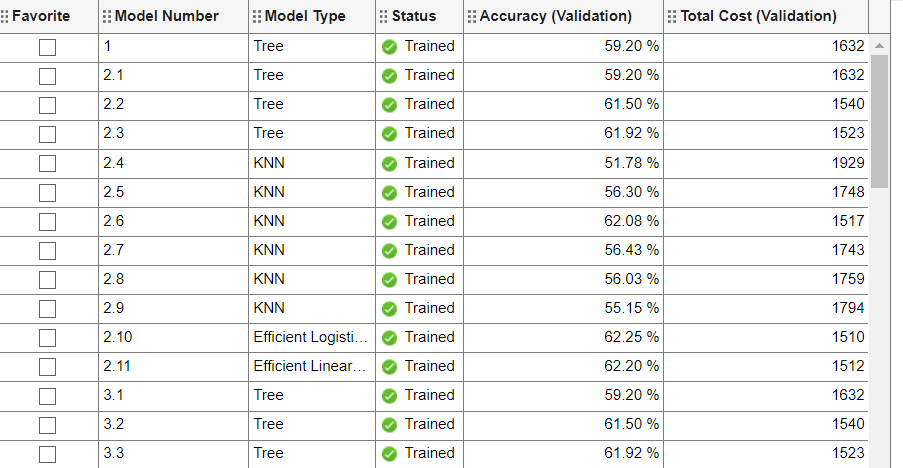

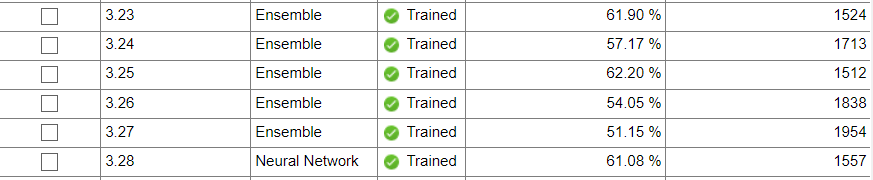

response = yInvIncTrain;
rng('default')
template = templateTree('MaxNumSplits', 3999);
classificationEnsemble = fitcensemble(...
    XsmallTrainTable, ...
    response, ...
    'Method', 'Bag', ...                      bagged tree
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),... 
    'Cost', [0 1; 3 0],...                    misclassification costs
    'KFold', 10,...                           10-fold validation
    'CrossVal','on')

classificationEnsemble =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Bag'
         PredictorNames: {'Risktolerance'  'Age'  'Financial Education'  'Income'  'Wealth'}
           ResponseName: 'Y'
        NumObservations: 4000
                  KFold: 10
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [100 100 100 100 100 100 100 100 100 100]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods


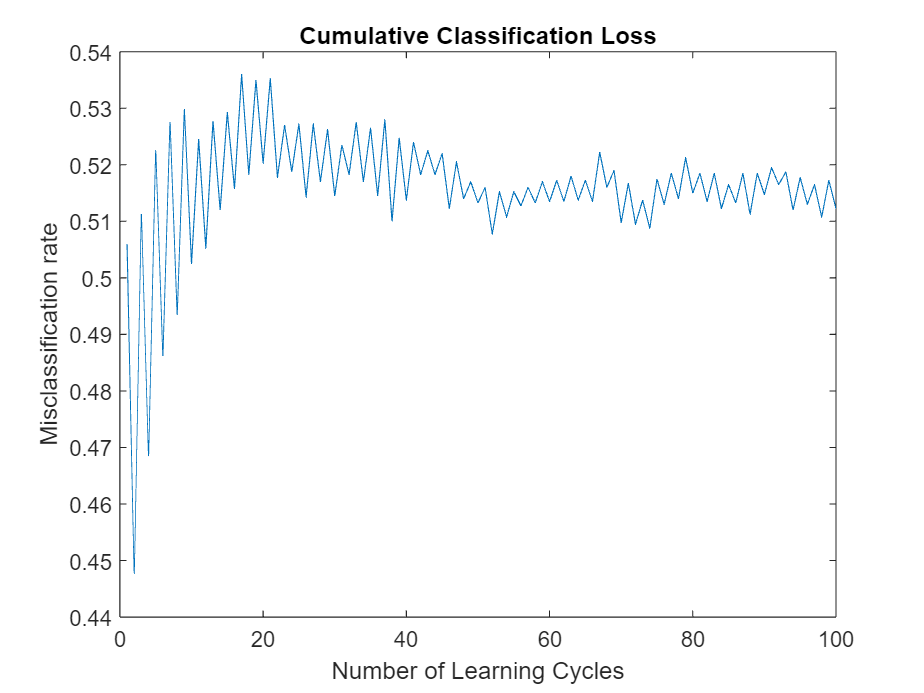

CVLoss = kfoldLoss(classificationEnsemble,'Mode','Cumulative');
figure;
plot(CVLoss);
xlabel('Number of Learning Cycles');
ylabel('Misclassification rate');
title('Cumulative Classification Loss')

estGenError = CVLoss(end)

estGenError = 0.5122

[labels, scores, cost] = kfoldPredict(classificationEnsemble);
tp = sum((labels == '1') & (response =='1'));
fp = sum((labels == '1') & (response =='0'));
fn = sum((labels == '0') & (response =='1'));
prec = tp / (tp + fp)

prec = 0.3799

rec = tp / (tp + fn)

rec = 0.5615

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.4532

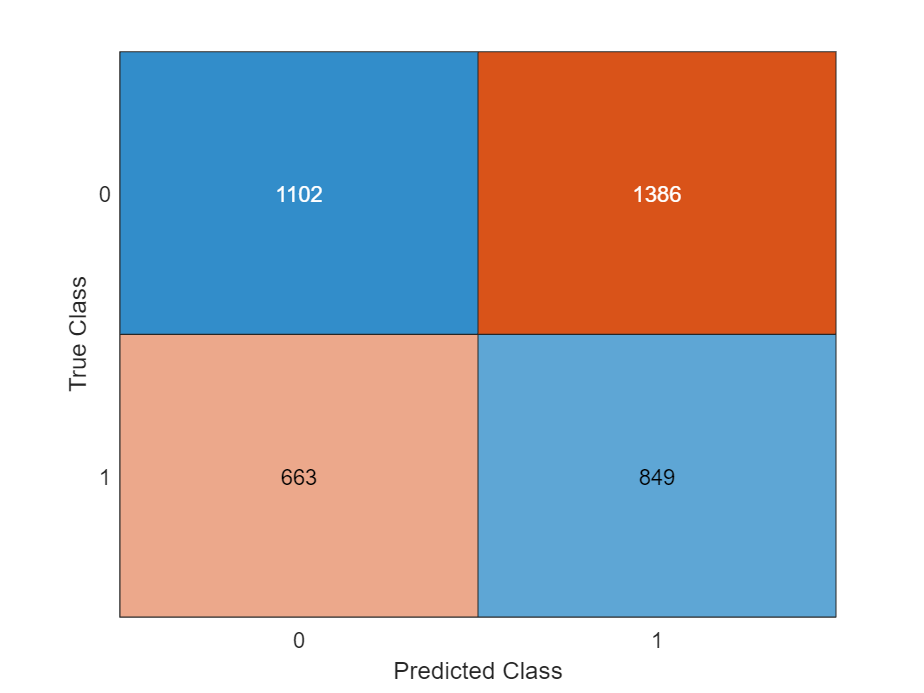

confusionchart(response, labels)

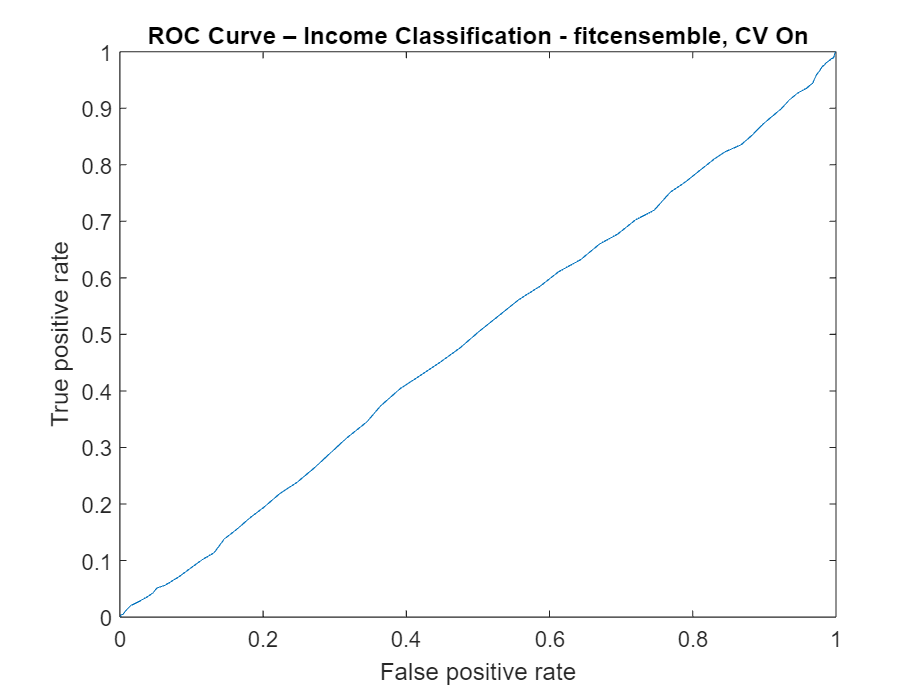

[X,Y,~,AUC] = perfcurve(response,scores(:,2),1);
figure
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve – Income Classification - fitcensemble, CV On')

AUC

AUC = 0.4919

classificationEnsemble = fitcensemble(...
    XsmallTrainTable, ...
    response, ...
    'Method', 'Bag', ...
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),...
    'Cost', [0 1; 3 0],...
    'CrossVal','off')

classificationEnsemble =   ClassificationBaggedEnsemble
           PredictorNames: {'Risktolerance'  'Age'  'Financial Education'  'Income'  'Wealth'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 4000
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
                FResample: 1
                  Replace: 1
         UseObsForLearner: [4000×100 logical]


  Properties, Methods


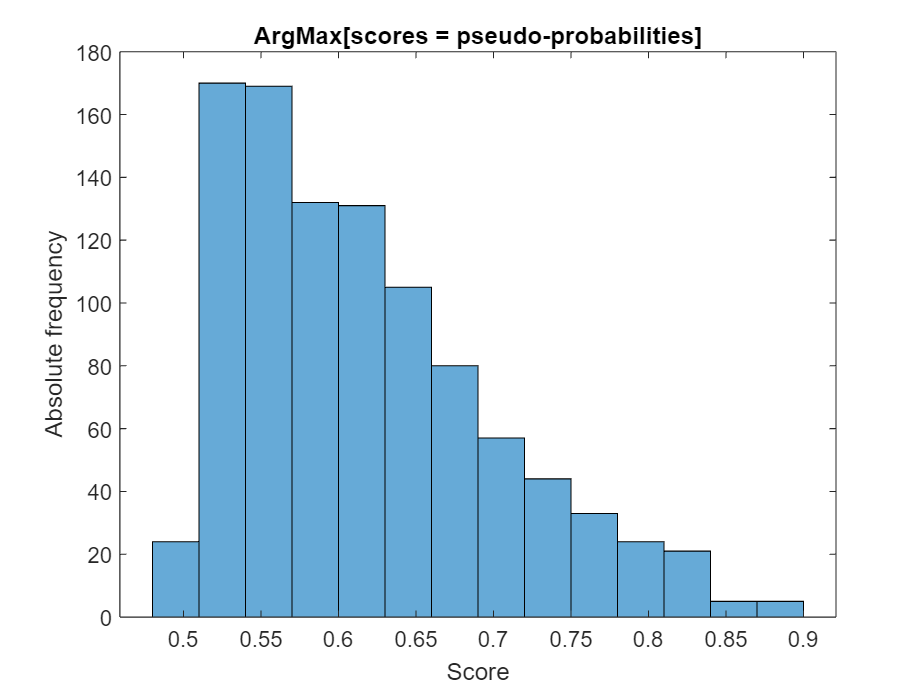

[labels,scores] = predict(classificationEnsemble,XsmallTestTable);
figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

tp = sum((labels == '1') & (yInvAccTest=='1'));
fp = sum((labels == '1') & (yInvAccTest=='0'));
fn = sum((labels == '0') & (yInvAccTest=='1'));
prec = tp / (tp + fp)

prec = 0.5070

rec = tp / (tp + fn)

rec = 0.5636

F1 = 2 * prec * rec / (prec + rec) 

F1 = 0.5338

rec = tp / (tp + fn)

rec = 0.5636

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.5338

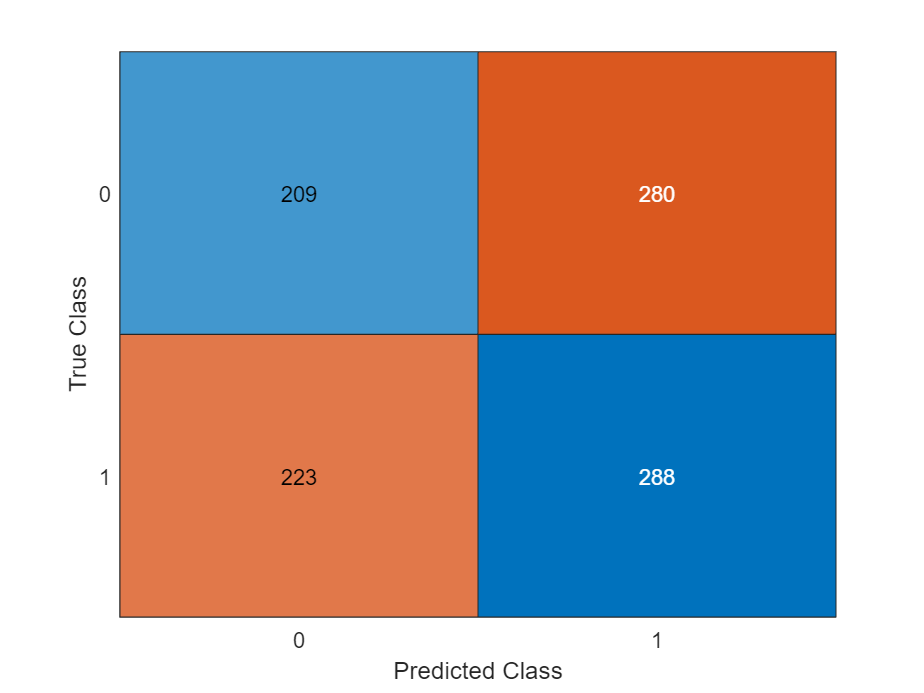

confusionchart(yInvAccTest, labels)

**Optimizing**

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.48525 |      1.5218 |     0.48525 |     0.48525 |   AdaBoostM1 |           23 |      0.86397 |            2 |
|    2 | Best   |     0.47025 |      18.267 |     0.47025 |     0.47085 |          Bag |          214 |            - |            2 |
|    3 | Accept |       0.487 |      14.932 |     0.47025 |     0.47139 |          Bag |          340 |            - |           91 |
|    4 | Accept |     0.48625 |      5.1024 |     0.47025 |   

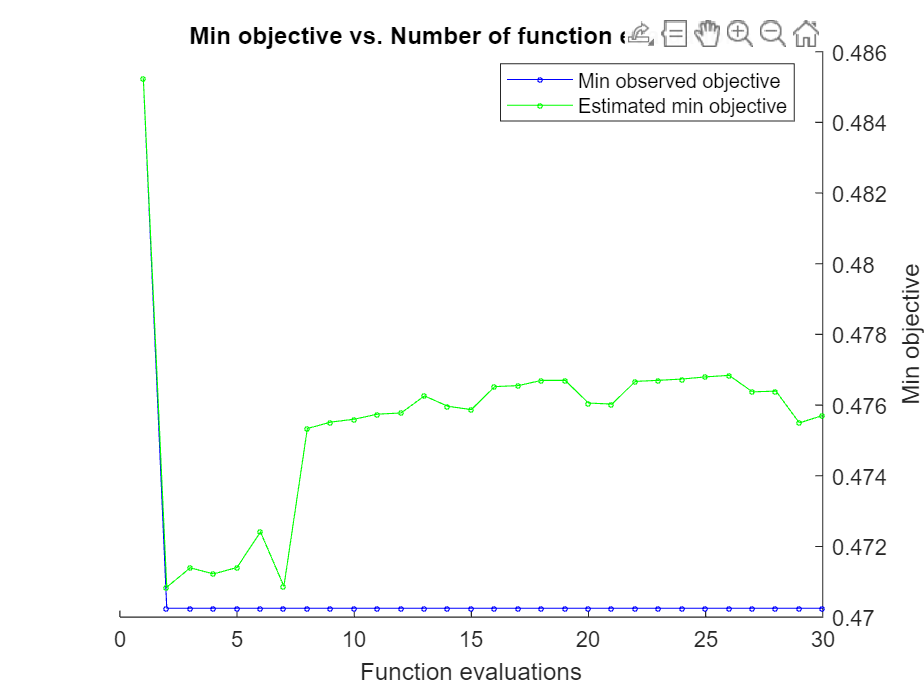


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 330.4975 seconds
Total objective function evaluation time: 315.2175

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             214              NaN            2     

Observed objective function value = 0.47025
Estimated objective function value = 0.47571
Function evaluation time = 18.2667

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MDLTA =   ClassificationBaggedEnsemble
                       PredictorNames: {'Risktolerance'  'Age'  'Financial Education'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 4000
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 214
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: [4000×214 logi

rng('default')          % setting seed for reproducibility
% ------------------------ Accumulation Investment - Classification -------------------------------------
t = templateTree('Reproducible',true);
MDLTA= fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'),'Cost', [0 1; 1.5 0])

% ------------------------ Income Investment - Classification -------------------------------------

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |       0.378 |      4.9826 |       0.378 |       0.378 |   LogitBoost |          259 |     0.035046 |         1275 |
|    2 | Accept |       0.448 |     0.53332 |       0.378 |     0.38469 |   AdaBoostM1 |           18 |      0.49466 |          953 |
|    3 | Accept |     0.46625 |       1.009 |       0.378 |     0.38396 |          Bag |           11 |            - |            7 |
|    4 | Accept |       0.429 |      13.626 |       0.378 |   

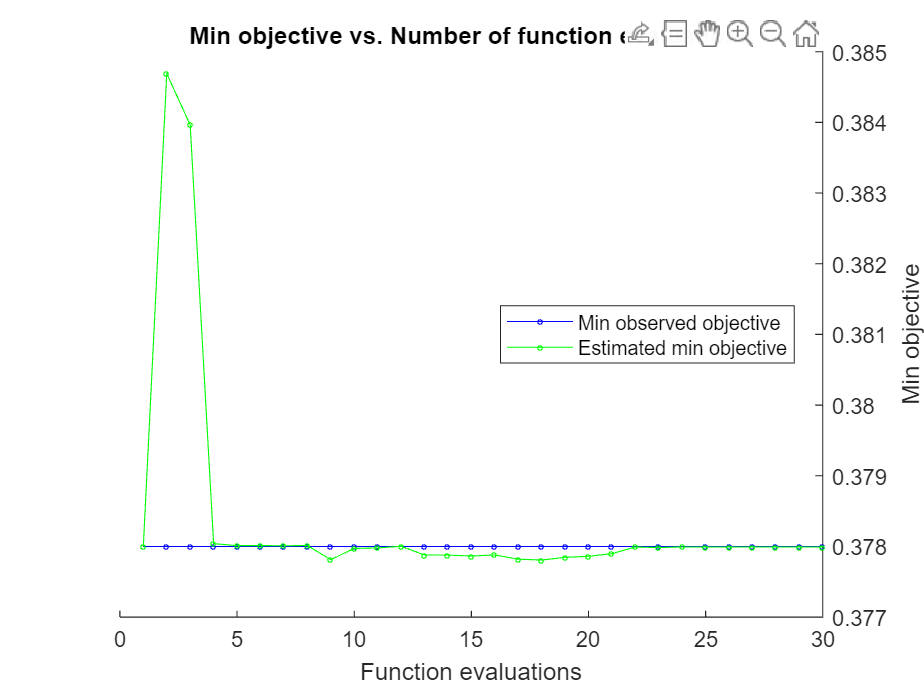


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 145.6098 seconds
Total objective function evaluation time: 136.4838

Best observed feasible point:
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________    ___________

    LogitBoost           259           0.035046        1275    

Observed objective function value = 0.378
Estimated objective function value = 0.37801
Function evaluation time = 4.9826

Best estimated feasible point (according to models):
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________

MDLTI =   ClassificationEnsemble
                       PredictorNames: {'Risktolerance'  'Age'  'Financial Education'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 4000
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 479
                               Method: 'LogitBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [479×1 double]
                   FitInfoDescription: {2×1 cell}


  Properties, 

rng('shuffle')
MDLTI=fitcensemble(XsmallTrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'),'Cost', [0 1; 1.5 0])

**Testing**

[labels_a,scores_a] = predict(MDLTA,XsmallTestTable);
tp = sum((labels_a == '1') & (yInvAccTest=='1'));
fp = sum((labels_a == '1') & (yInvAccTest=='0'));
fn = sum((labels_a == '0') & (yInvAccTest=='1'));
prec = tp / (tp + fp)

prec = 0.5074

rec = tp / (tp + fn)

rec = 0.7339

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.6000

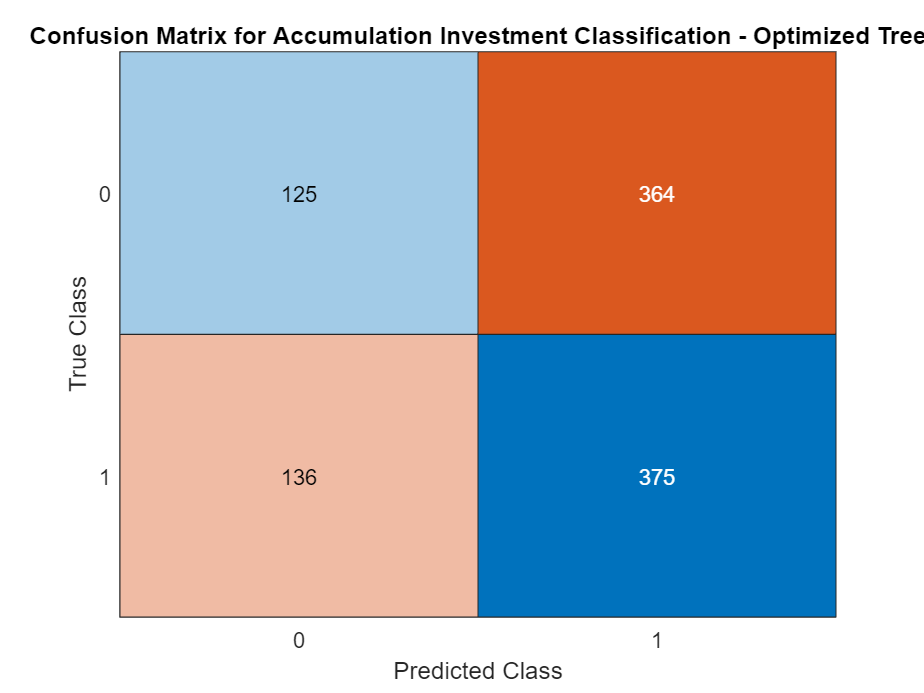

figure
confusionchart(yInvAccTest, labels_a)
title('Confusion Matrix for Accumulation Investment Classification - Optimized Tree')

[labels_i,scores_i] = predict(MDLTI, XsmallTestTable);
tp = sum((labels_i == '1') & (yInvIncTest == '1'));
fp = sum((labels_i == '1') & (yInvIncTest == '0'));
fn = sum((labels_i == '0') & (yInvIncTest == '1'));
prec = tp / (tp + fp)

prec = NaN

rec = tp / (tp + fn)

rec = 0

F1 = 2 * prec * rec / (prec + rec)

F1 = NaN

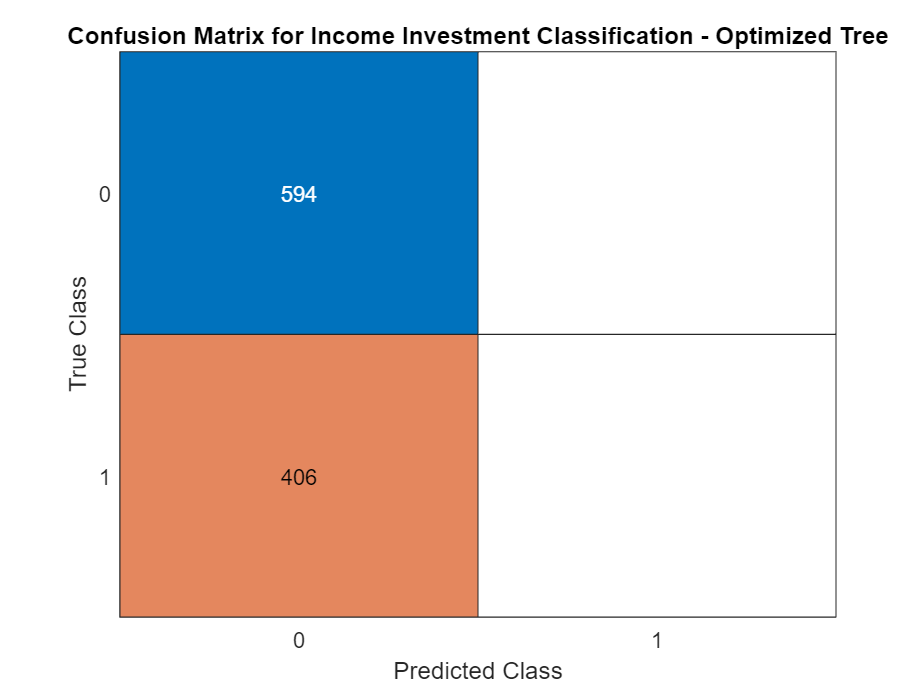

figure
confusionchart(yInvIncTest, labels_i)
title('Confusion Matrix for Income Investment Classification - Optimized Tree')

**Recommending products**

**!!! Here we have to decide which labels we are going to use**

% Retrieving clients IDs
nObs = size(Data,1);
nObsTrain = round(0.80*nObs);
idxPermutation = randperm(nObs);
ClientID = Data.ID(idxPermutation);
ClientIDTest = ClientID(nObsTrain+1:end,:);
TargetClientID = ClientIDTest(labels_i=='1' | labels_a =='1');

% Retrieving clients' risk propensities and Risk Tolerance 
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);
ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity(:,1) = ClientRiskPropensityTest.*(labels_i=='1')- (labels_i == '0');
TargetClientRiskPropensity(:,2) = ClientRiskPropensityTest.*(labels_a=='1')- (labels_a == '0');
TargetClientRiskPropensity(all(TargetClientRiskPropensity(:,1:2))==-1,2)=[];

A null assignment can have only one non-colon index.

AccumulationProducts = Products(Products.Type == 1,:);
IncomeProducts = Products(Products.Type == 0,:);

NBA_IDProduct = [];
RecommendedRiskLevel = [];
minRisk = min(AccumulationProducts.Risk);
product_ID =cast(AccumulationProducts.ID, "uint16");
client_ID = cast(TargetClientID, "uint16");

for i = 1: size(TargetClientRiskPropensity, 1)
    if TargetClientRiskPropensity(i)> minRisk
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<TargetClientRiskPropensity(i)));
        NBA_IDProduct = [NBA_IDProduct; product_ID(AccumulationProducts.Risk == M)];
    else
        % no suitable product in the product range
        NBA_IDProduct = [NBA_IDProduct; 0];
        M = 0;
    end
    RecommendedRiskLevel = [RecommendedRiskLevel; M];
end

% recommendations
NBA = [client_ID NBA_IDProduct];

figure
c = linspace(0,1,length(TargetClientRiskPropensity));
scatter(TargetClientRiskPropensity, RecommendedRiskLevel, [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')
